# RSX Satellite Simulation Caller

% Simulate Full Mission for RSX CONSat
%
% © Lance Ayers
% 18 February 2026

## Simulation Parameters

clear;

simIn.runTime = 90;

% Simulation Sample Times
simIn.simTs =  1/50;       % simulation time step
% simIn.ctrlTs = 1/50;       % controller time step (not implemented)
% simIn.cvtTs =  1/5;        % cvt time step (not implemented)

% Timed Events (sec)
ejectDelay = 5;             % wait time after ejection to enable controller (sec)
initialAlignmentEnd = 20;   % align to initial guess end time
targetFound = 60;           % time when target is found
searchRate = deg2rad(10);   % yaw search rate (rad/sec)
targetLocation = deg2rad([0,-10,5]);    % target location (rad)

% Initial Conditions
simIn.att0 = [0 0 0];                   % initial attitude (rad)
simIn.w0 = [0.5 0.3 0.2]*deg2rad(5);    % initial rates (rad/sec)

## Model Parameters

% Vehicle Principal Moments of Inertia (kg-m^2)
Jxx = 0.002139; Jyy = 0.00207; Jzz = 0.00199;   % vehicle
simIn.Jv = diag([Jxx,Jyy,Jzz]); 

% Reaction Wheel Parameters
simIn.J_rw = 1.7469e-05;                        % reaction wheel inertia (kg-m^2)
simIn.alpha_rw = 100;                           % reaction wheel acceleration (rad/s^2)
simIn.trq_rw = simIn.J_rw*simIn.alpha_rw;       % reaction wheel torque (N-m)
simIn.maxOmega_rw = 2000*2*pi/60;               % max reation wheel speed (rad/s)
maxRate_v = rad2deg(simIn.J_rw/Jxx*simIn.maxOmega_rw);  % maximum vehicle rate (deg/s)

## PD Gain

% Rate Damping PD Gain
rdKp = diag([1 1 1]);       % proportional (error) gain (keep 0 for rate damp)
rdKd = diag([1 1 1]);       % derivative (rates) gain
simIn.rdK = [rdKp rdKd];    % PD gain

% Search PD Gain
sKp = diag([0 1 1]);        % proportional (error) gain (yaw gain 0 for search)
sKd = diag([1 1 1])*10;     % derivative (rates) gain
simIn.sK = [sKp sKd];       % PD gain

## LQR Gain

q = eul2quat([0,0,0]);              % quaternion values to linearize
q_lin = q(2:4)';
   
w_lin = [0; 0; 0];                  % rate values to linearize
x_lin = [q_lin; w_lin];             % linearized state

Q = diag([5, 5, 5, 1, 1, 1]);       % Q matrix for LQR
R = eye(3);                         % R matrix for LQR

## LQR Linearization

% Symbolic Terms for Nonlinear Model
syms q1 q2 q3 w1 w2 w3 u1 u2 u3

J = simIn.Jv;
J_inv = J^-1;
q = [q1; q2; q3];
w = [w1; w2; w3];
u = [u1; u2; u3];   % control input
x = [q; w];         % state

q0 = sqrt(1-q1^2-q2^2-q3^2);    % q0 (ensures q is a unit vector)

Omega = [q0 -q3 q2; q3 q0 -q1; -q2 q1 q0];

f = [0.5*Omega*w; J^-1*u];      % Nonlinear EOM

% Compute A and B
for idx1 = 1:size(f,1)
    for idx2 = 1:size(x,1)
        A_nl(idx1,idx2) = diff(f(idx1),x(idx2));
    end
    for idx3 = 1:size(u,1)
        B_nl(idx1,idx3) = diff(f(idx1),u(idx3));
    end
end

## Linearized Model

% Linearize A and B about q and w
A = double(subs(A_nl,x,x_lin));
B = double(subs(B_nl,x,x_lin));
C = eye(6);

sys_c = ss(A,B,C,0);                    % continuous open-loop model
[lqrK, S, P] = lqr(sys_c,Q,R);          % continuous LQR gains
simIn.lqrK = lqrK;

## Back-End

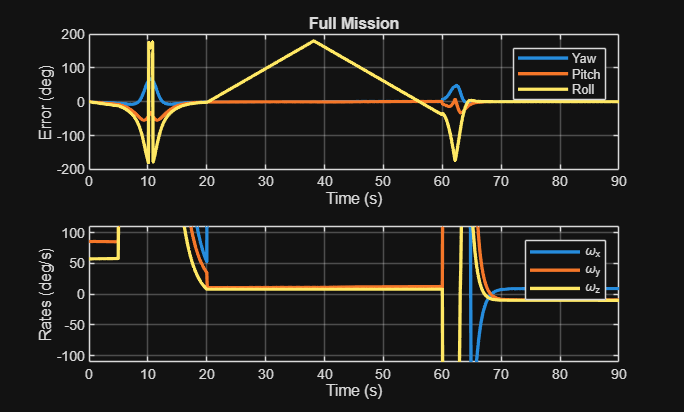

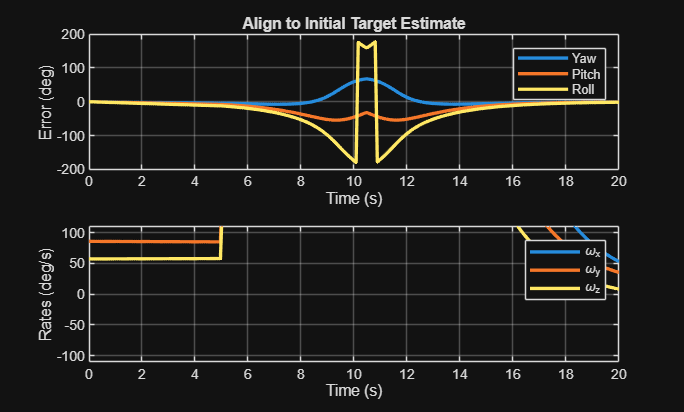

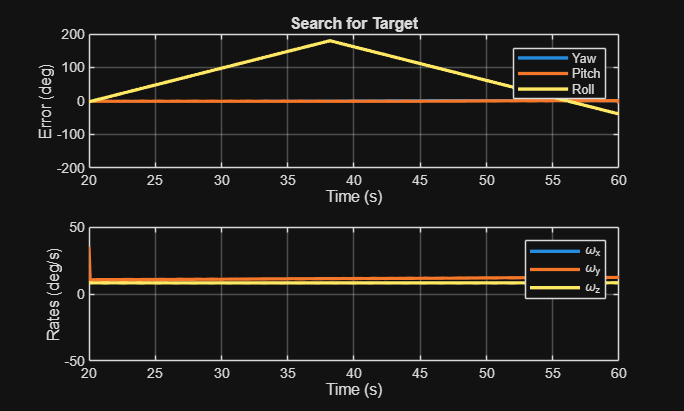

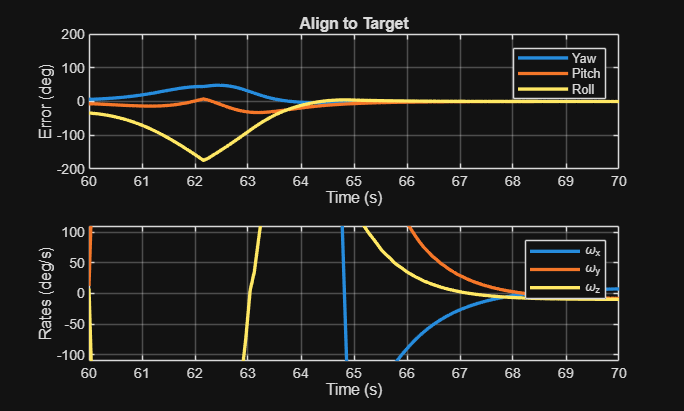

% Timer Events
simIn.ctrlModes = [0 1 2 3];
simIn.ctrlTimes = [0 ejectDelay initialAlignmentEnd targetFound];

% Format Targets
trgtQuat = eul2quat(targetLocation);
simIn.trgt(1,:) = zeros(6,1);
simIn.trgt(2,:) = zeros(6,1);
simIn.trgt(3,:) = [zeros(3,1);searchRate;0;0];
simIn.trgt(4,:) = [trgtQuat(2:4)';zeros(3,1)];

% Call and Run Simulation Model
sIn = Simulink.SimulationInput('rsxSatSim.slx');
sIn = sIn.setVariable('simIn', simIn);
out = sim(sIn);
out = sim('rsxSatSim.slx');

rsxSatSim_postProcessor